## **Pump sizing**

#### **Additional piping and fitting and radiatior**

In the previous sections [ColdPlate](matlab:open('.\ColdPlate.mlx')) we have already determined expected pressure losses at nominal conditions for the cold plate. Adding to that will be additional pressure lossed for piping and fittings. Similar as it is done in the Simscape components, we will determine length of piping and the aggregated equivalent length of additional fittings. We are assuming an overall piping length of 3 m. And we will roughly account for the equivalent length of 4 90° elbow bends. 

Only a small pressure drop is expected for the radiator we will add a margin to the overall pressure drop to account for this. 

#### Determine pressure drop for additional piping

pipingD         = simscape.Value(10, "mm");   % Additional diameter
pipindDh        = pipingD;                    % Hydraulic diameter
pipingLength    = simscape.Value(2, "m");     % Additional piping length
equivalentLengthRatio = 4*60;
equivalength    = equivalentLengthRatio*pipindDh;
pipingAddLength = simscape.Value(1, "m");     % Aggegrate length of additional components
pipingArea      = pi*(pipingD/2)^2;           % Additional elements cross-sectional area
pipingRoughness = simscape.Value(15e-6, "m"); % Piping roughness

Determine pressure loss in Simscape model

open_system("example_Piping")

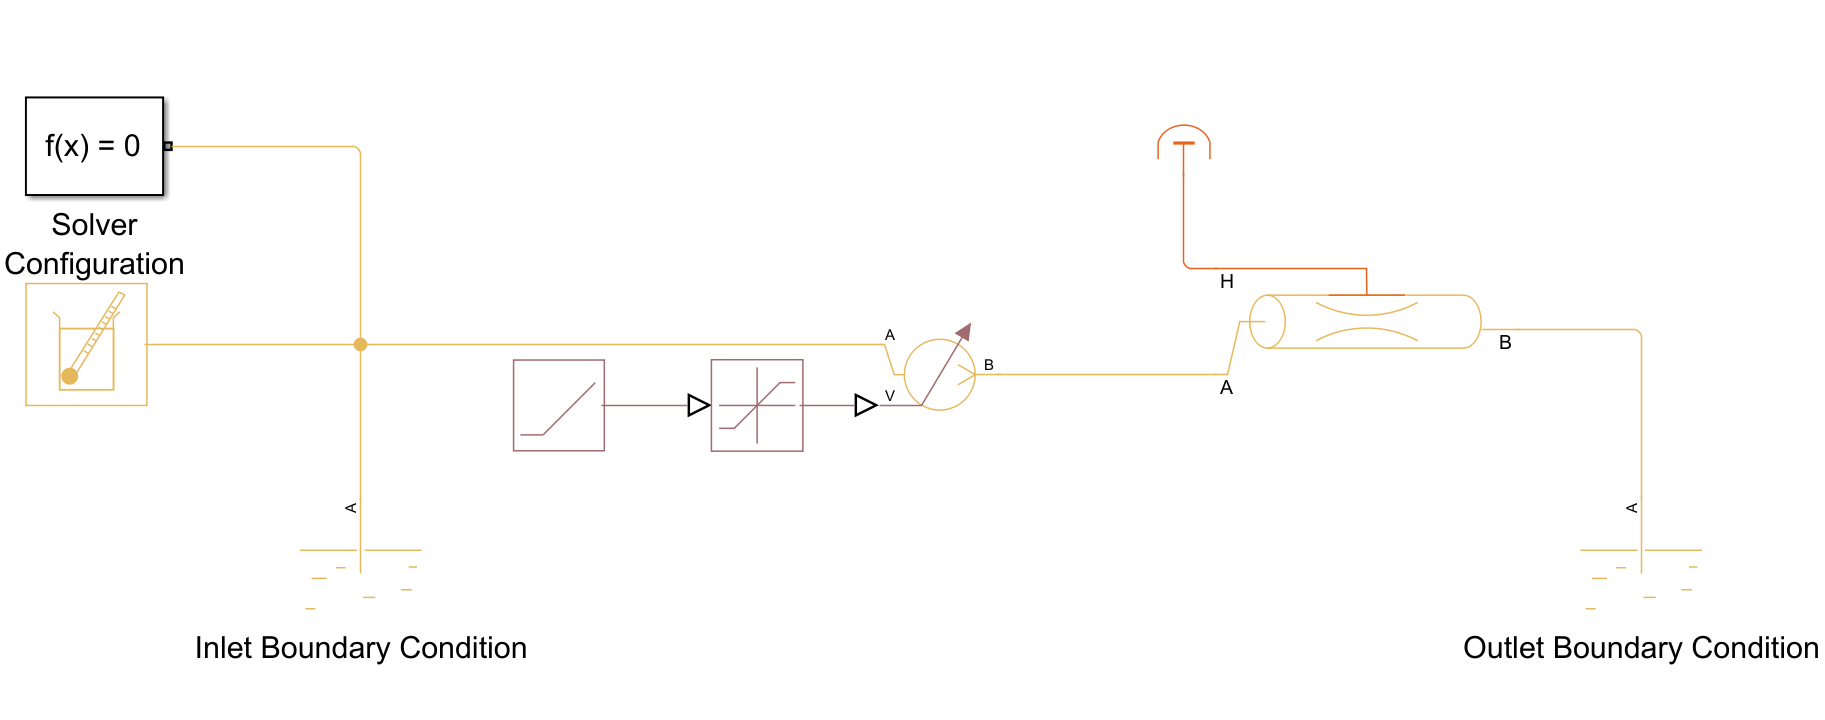

Again, we are using a Pipe (TL) block to represent the additional piping and fitting elements. The pipe geometry is parameterized the above values. As in previous models we set the cross-sectional areas of connected ports to similar values. Here, this is chosen to be the piping cross-sectional area. 

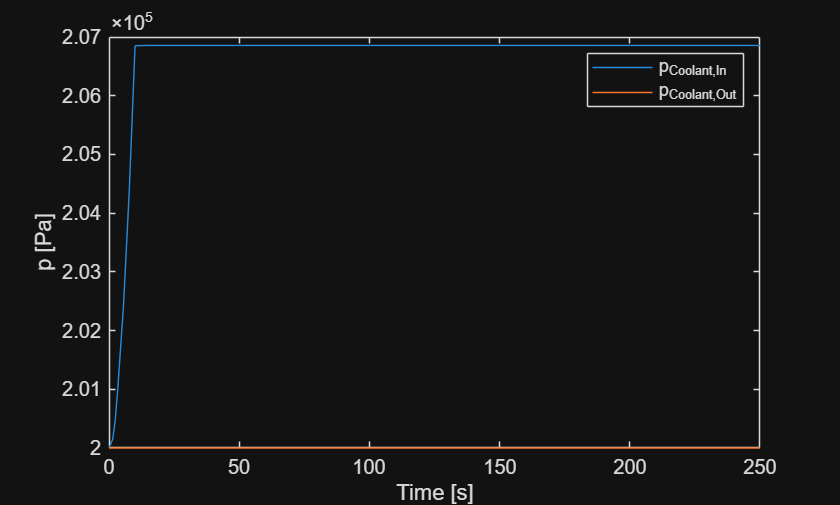

simInp = Simulink.SimulationInput("example_Piping");
simInp = simInp.setModelParameter("StopTime","250");

simOut = sim(simInp);

pPipingIn       = simOut.simlog.Pipe_TL.A.p.series.values("Pa");
pPipingOut      = simOut.simlog.Pipe_TL.B.p.series.values("Pa");

dpPiping        = pPipingIn-pPipingOut;

figure
plot(simOut.tout,[pPipingIn,pPipingOut])
ylabel("p [Pa]")
xlabel("Time [s]")
legend("p_{Coolant,In}","p_{Coolant,Out}")
hold off


disp(dpPiping(end))

   6.8563e+03



#### Pump parameterization

The overall pressure drop determined for the cold plate (in [ColdPlate](matlab:open('.\ColdPlate.mlx'))) and the additional piping gives a overall pressure loss of rougly 0.07 bars. Adding a margin to account for insecurities as well as the pressure losses caused by the radiator, we will work with a overall pressure loss value of 0.08 bars. The system will be using a centrifugal pump. The suitable Simscape Fluids component [Centrifugal Pump (TL)](https://www.mathworks.com/help/releases/R2025a/hydro/ref/centrifugalpumptl.html) offers different paramaterization options. 

We will work with a representative vendor data sheet and extract the pump curves for use in the Simscape block. In the parameterization option 1D tabulated data - head and break power vs. capacity at reference speed, the pump head and break power and respective capacity will be provided as a lookup table. 

%ToDo: Update image with scaled version

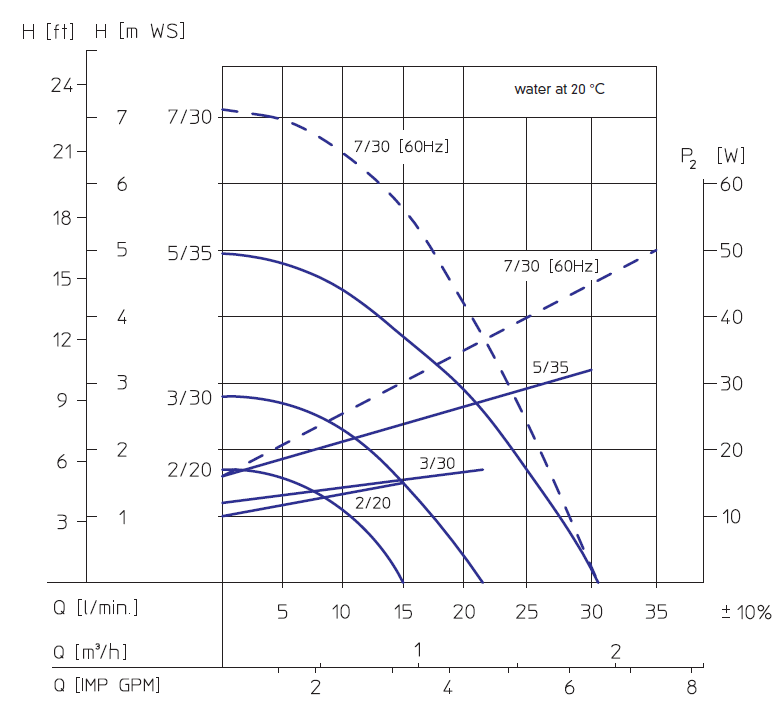

We can use the [Graph Data Extractor](https://www.mathworks.com/help/releases/R2025b/simscape/ref/graphdataextractor.html) to extract the points for the relevant pump model:

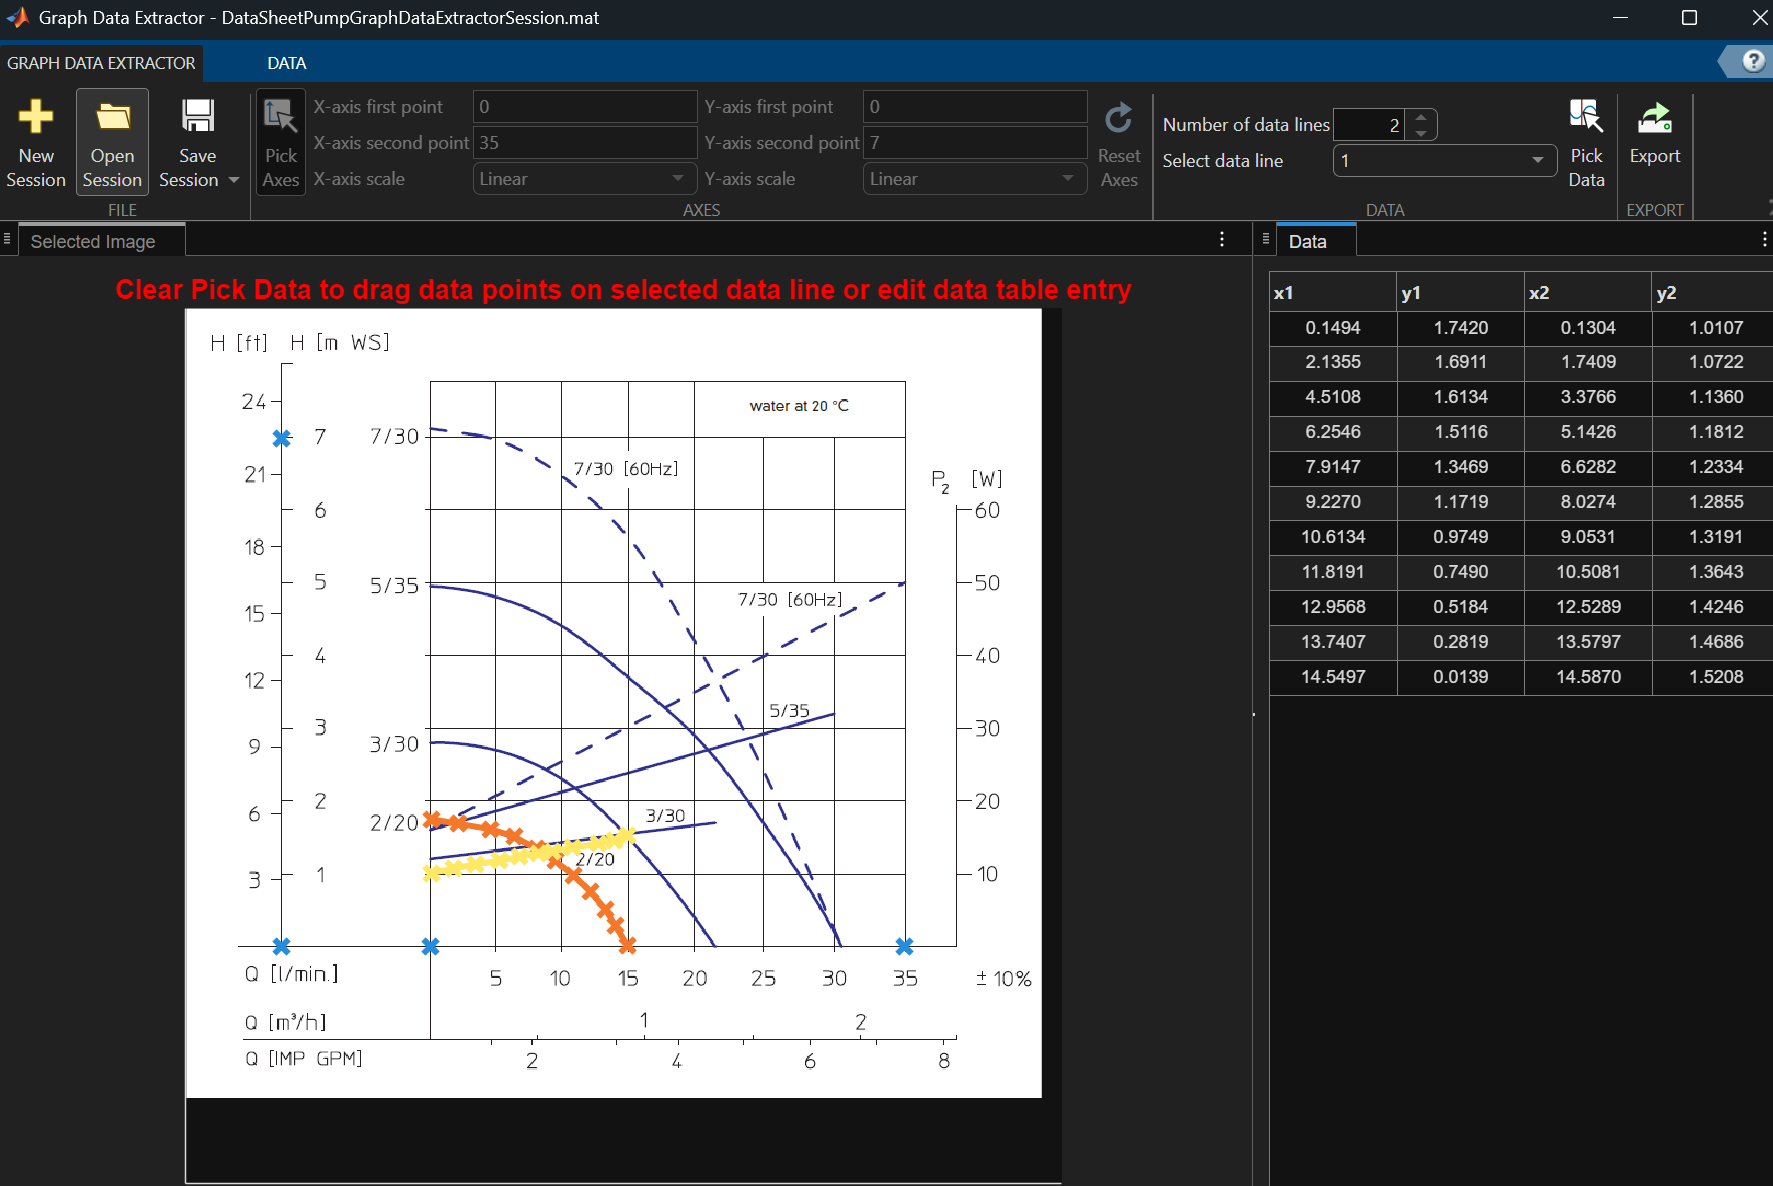

Load values from the previously created Graph Data Extractor session. See the script [createPumpData](matlab:open('..\Docs\createPumpData.m')) how the data from the Graph Data Extractor is processed. 

load(projRoot+"\Data\pumpData.mat")

We will use a  pump inertia value of 1e-5 kg*m^2. 

pumpInertia     = simscape.Value(1e-5, "kg*m^2"); 
pumpRefSpeed    = simscape.Value(2850, "rpm");

Test pump in Simscape model

open_system("example_Pump")

The test model uses a Pressure Source (TL) block to mimick a load, we use an Inport block connected to that to load a test vector into the model. To test the pump range, we ramp up the load beyond the expected maximum pressure drop. You can also validate the pump curve with the current paramterization by right-clicking the pump component and selecting *Fluids->Plot Pump Characteristics:*

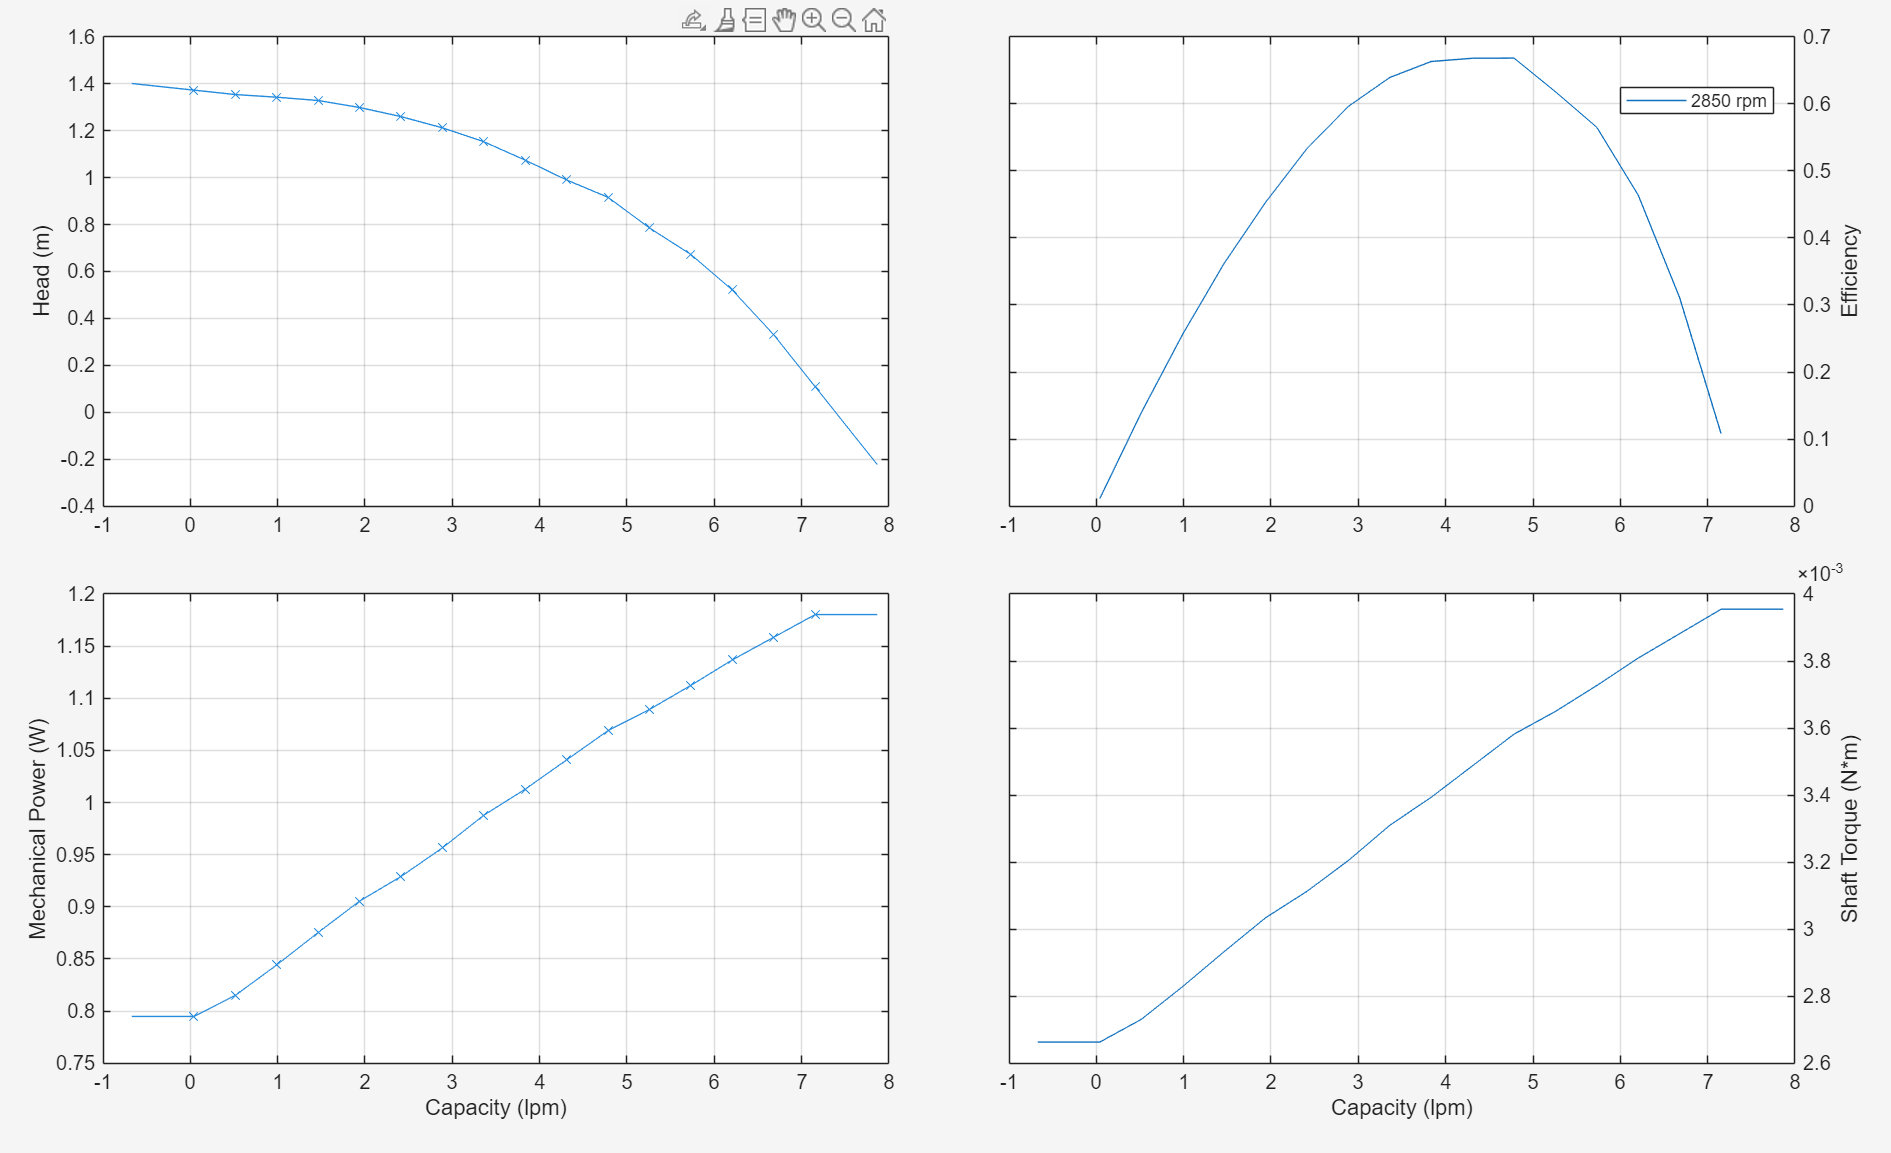

Note that there is also an Inertia component connected to the mechanical R port of the pump. It is good practice to add an inertia (or compliance) to avoid instablities with instantaneous changes.  

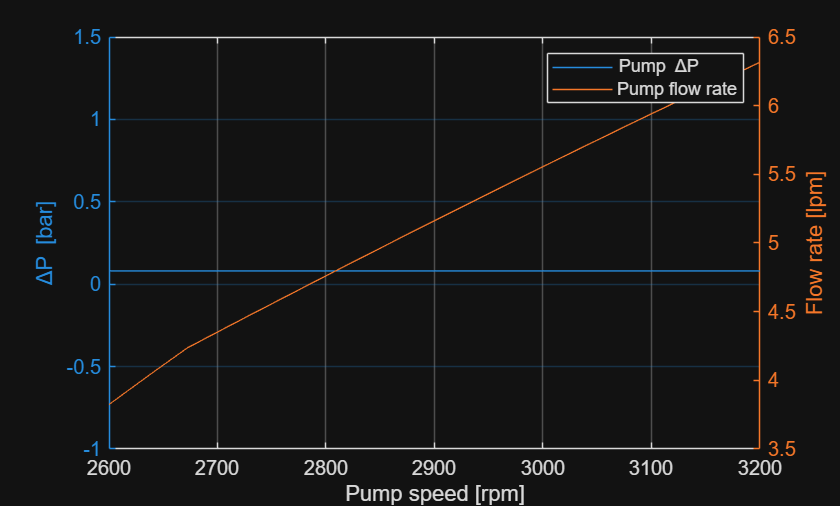

dpReq = simscape.Value(0.08, "bar");                            % Required pressure drop used for testing

tInPumpTest     = [0;50;60];  
loadInPumpTest  = [dpReq.value("bar");dpReq.value("bar");dpReq.value("bar")]; % Pressure load used for testing 
speedInPumpTest  =[2600;2600;3200];                                           % Fan speed used for testing 
speedRefInit     = simscape.Value(speedInPumpTest(1),"rpm"); 

simInp = Simulink.SimulationInput("example_Pump");
simInp = simInp.setModelParameter("StopTime","60");
simInp = simInp.setExternalInput([tInPumpTest,loadInPumpTest,speedInPumpTest]);
simOut = sim(simInp);

pLoad = simOut.simlog.Pressure_Source_TL.P.series.values("bar");
VDotPump  = simOut.simlog.Centrifugal_Pump_TL.q_A.series.values("lpm");
speedPump = simOut.simlog.Centrifugal_Pump_TL.omega.series.values("rpm");
effPump = simOut.simlog.Centrifugal_Pump_TL.efficiency.series.values("1");

figure
yyaxis left
plot(speedPump,pLoad);
ylabel("\DeltaP [bar]")
yyaxis right
plot(speedPump,VDotPump);
ylabel("Flow rate [lpm]")
xlabel("Pump speed [rpm]")
legend("Pump \DeltaP","Pump flow rate")
grid on

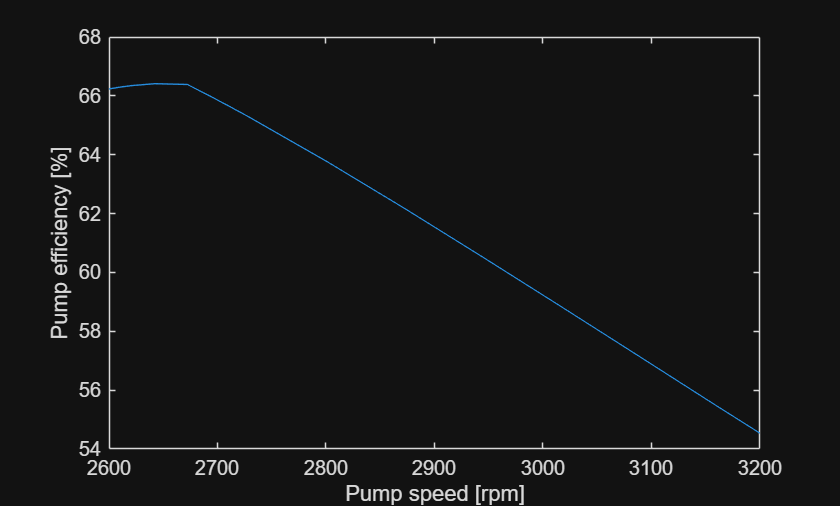

figure
plot(speedPump,effPump*100);
ylabel("Pump efficiency [%]")
xlabel("Pump speed [rpm]")

In the speed range tested for the given pressore load, pump created between roughly 4 and 6.5 lpm. We determined an operating point of 5.75 lpm, for the desired cooling capacity. 

From the plot we can see, that this relates to roughly 3075 rpm.

#### Heat produced by pump

To design the radiator in the next step, we will also have to account for the heat produced by the pump. We will run the pump at nominal operating conditions to extract the This can be extracted from the Simscape logging object as well:

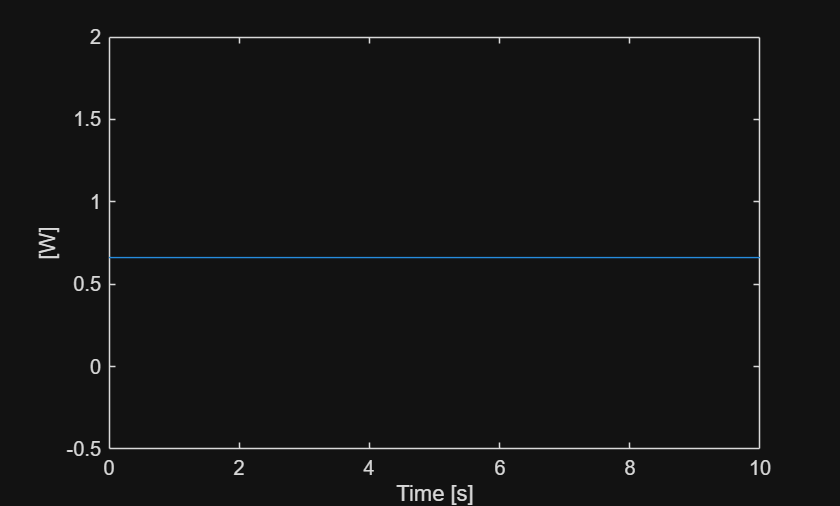

tInPumpTest     = [0;10];  % s
loadInPumpTest  = [dpReq.value("bar");dpReq.value("bar")]; 
speedInPumpTest = [3075;3075]; 
speedRefInit    = simscape.Value(speedInPumpTest(1),"rpm"); 

simInp = Simulink.SimulationInput("example_Pump");
simInp = simInp.setModelParameter("StopTime","10");
simInp = simInp.setExternalInput([tInPumpTest,loadInPumpTest,speedInPumpTest]);

simOut = sim(simInp);

efficiencyPump = simOut.simlog.Centrifugal_Pump_TL.efficiency.series.values("1");
mechanicalPwrPump = simOut.simlog.Centrifugal_Pump_TL.mechanical_power.series.values("W");
heatPump = efficiencyPump.*mechanicalPwrPump;

figure
plot(simOut.tout,heatPump);
xlabel("Time [s]")
ylabel("[W]")